# Konzeptfahrzeug HElmar - Antriebseinheit

*Prof. Dr.-Ing. Ralf Schuler, Esslingen University*

Dieses Live-Skript war Basis für die Prüfung KFZSYS im SS2022.

Betrachtet wird eine Einzelradlenkung eines elektrisch angetriebenen Forschungsfahrzeuges mit Radnabenantrieb.

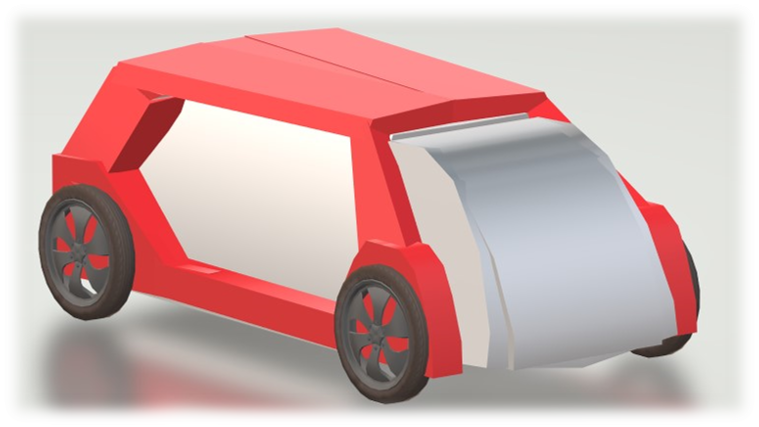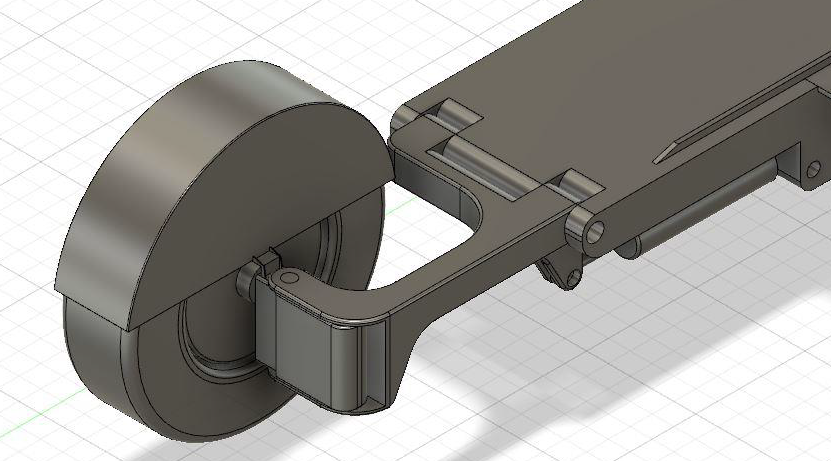

## Daten Gesamtfahrzeug

m=800; % Rover mit 4 QS273 Motoren a 30kg: 450 kg; Batterie 190 kg, Fahrer 75 kg; Beifahrer 65 kg; 
g=9.81;
fR=0.01;
rA=0.35; % bei 18" (Felge siehe https://www.felgenshop.de/rc-design-rc30-schwarz-lackiert-18-zoll-0620071118/cupra-born-k1-alufelgen/0-0l-70kw-born-77-e-boost-95-ps/)
rho=1.2;
cw=0.31;
A=2;
cwA=cw*A;

%Masse Fahrgestell & 300 kg \\
%$c_w$ Wert Fahrgestell & 0,4 \\
%Stirnfläche Fahrgestell & 0,86 m\textsuperscript{2} \\
%Antriebswirkungsgrad $\eta_A$ & 0,95 \\
%Drehmassenzuschlagsfaktor $\epsilon$ & 0,0463 \\


## Fahrzeugantrieb

Gegebener Datensatz von QS Motors 8000V, 72V

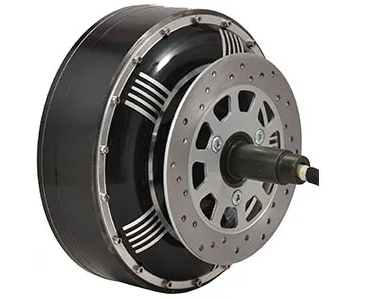

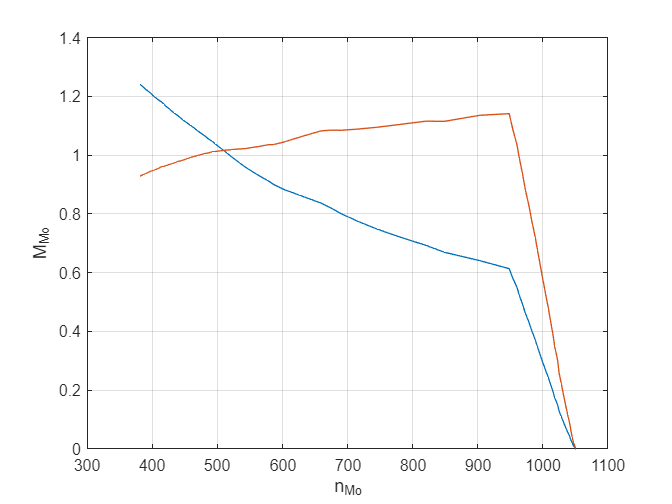

load('QS273.mat')
P_Mo_out_ref=cell2mat(W50H273V3Measurement72V(2:end,2));
P_Mo_in_ref=cell2mat(W50H273V3Measurement72V(2:end,3));
M_Mo_ref=cell2mat(W50H273V3Measurement72V(2:end,5));
n_Mo_ref_rpm=cell2mat(W50H273V3Measurement72V(2:end,1));
eff_Mo=cell2mat(W50H273V3Measurement72V(2:end,4));

figure
plot(n_Mo_ref_rpm,M_Mo_ref./150)
hold on
grid on
plot(n_Mo_ref_rpm,P_Mo_out_ref./8000)
xlabel('n_{Mo}')
ylabel('M_{Mo}')

### Datenaufbereitung und Generierung eines adäquaten Motorkennfeldes

Datensatz ist für 72V gemessen. Anpassung der Daten auf HElmar Batteriespannung von 48V. 

U_Mo_nom = 48; % Auslegungspannung
kv =       14.9; % Angabe auf https://www.miromax.lt/en/m-6/c-26/c-49-electric_car_conversion_kits/product-783-qs-273_8000w_electric_motor_for_car#specification
R_A =      0.016; % gegeben auf https://endless-sphere.com/forums/viewtopic.php?t=80635

Leerlaufdrehzahl

n0_Mo_rpm = kv*U_Mo_nom

n0_Mo_rpm = 715.2000

hypothetische Geschwindigkeit bei Leerlaufdrehzahl (als Orientierungswert)

v0_kph = n0_Mo_rpm*pi/30*rA*3.6

v0_kph = 94.3684

Motorkonstante aus kv

c_Mo = U_Mo_nom/(2*pi/60*n0_Mo_rpm)

c_Mo = 0.6409

                    
Mst_Mo=U_Mo_nom/R_A*c_Mo

Mst_Mo = 1.9227e+03

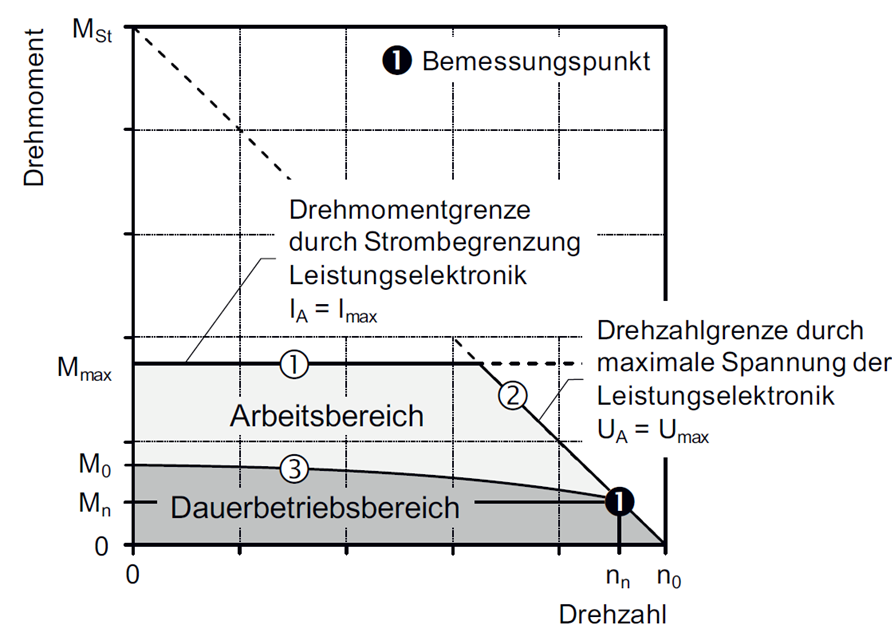

**ACHTUNG** **Ursprüngliche Annahme NICHT MEHR GÜLTIG: 4000W pro Motor bei 48V. Hier nochmal überdenken, denn der Motor geht ab Eckdrehzahl in Feldschächbetrieb. Dann gilt die "normale Gleichung der Kennlinie" nicht mehr ...**

%P_Mo_nom = 4000; 

Momente, bei denen mit den Motordaten jeweils 4000W entstehen.

Allgemein gilt für die Motordrehzahl: $n_{Mo}=\frac{U_A}{2\pi\cdot c_{Mo}}-\frac{R_A}{2\pi c_{Mo}^2}M_{Mo}$

Daraus wird für die Leistung: $P_{Mo} = n_{Mo}\cdot 2\pi \cdot M_{Mo}=\frac{U_A}{c_{Mo}}M_{Mo}-\frac{R_A}{c_{Mo}^2}M_{Mo}^2 \rightarrow 0 = \frac{R_A}{c_{Mo}^2}M_{Mo}^2 - \frac{U_A}{c_{Mo}}M_{Mo} + P_{Mo}$

Die Lösung der quadratischen Gleichung liefert Momente, bei denen der Motor mit der angegeben Kennlinie ($U_A$, $R_A$) 4000W abgibt.


$$M_{{Mo}_{1/2}}=\frac{-\frac{U_A}{c_{Mo}} \pm \sqrt{\frac{U_A^2}{c_{Mo}^2}- 4\cdot \frac{R_A}{c_{Mo}^2} \cdot P_{Mo}}}{2 \cdot \frac{R_A}{c_{Mo}^2}}$$


Die Wurzel wird dabei Null, wenn $U_A^2 = 4 \cdot R_A \cdot P_{Mo}$. Daraus lassen sich ggf. max. Ankerwiderstand und min. Spannung ermitteln, mit welchen gerade noch 4000 Abgabe erfolgen kann (Motorkennlinie bildet Tangente an Leistungskennlinie).

%tmpM=roots([R_A/c_Mo^2 -U_Mo_nom/c_Mo P_Mo_nom]);
%M_Mo1 = tmpM(2)
%I_Mo1 = M_Mo1/c_Mo

Die Drehzahl beim genannten Moment ergibt sich wiederum aus: $n_{Mo}=\frac{U_A}{2\pi\cdot c_{Mo}}-\frac{R_A}{2\pi c_{Mo}^2}M_{Mo}$

%n_Mo1_rpm=(U_Mo_nom/(2*pi*c_Mo)-R_A/(2*pi*c_Mo^2)*M_Mo1)*60
%v_Mo1_kph = n_Mo1_rpm*pi/30*rA*3.6

Stadtgeschwindigkeit $v_{54}$=54 kmh

%v_54_kph=54;
%n54_Mo_rpm = max(v_54_kph/3.6)/rA*30/pi
%M54_Mo = P_Mo_nom/(pi/30*n54_Mo_rpm)
%I54 = M54_Mo/c_Mo
%U54 = R_A*I54 + c_Mo*n54_Mo_rpm*pi/30
%M_Mo_plot = [M54_Mo,M54_Mo,[M54_Mo:-2:M_Mo1],M_Mo1,0];
%n_Mo_plot_rpm = [0,n54_Mo_rpm,P_Mo_nom./[M54_Mo:-2:M_Mo1]*30/pi,n_Mo1_rpm,n0_Mo_rpm];

%figure
%plot(n_Mo_plot_rpm,M_Mo_plot,'k')
%grid on
%ylim([0 100])
%xlabel('n_{Mo}')
%ylabel('M_{Mo}')

**KORREKTUR: Drehmoment bis zu Eckdrehzal konstant (=Grunddrehzahlbereich) **

M_Mo_cont = 93.3;
n_Mo_cont_rpm =(U_Mo_nom/(2*pi*c_Mo)-R_A/(2*pi*c_Mo^2)*M_Mo_cont)*60

n_Mo_cont_rpm = 680.4941

P_Mo_cont = M_Mo_cont*n_Mo_cont_rpm*pi/30

P_Mo_cont = 6.6487e+03

v_Mo_cont_kph = n_Mo_cont_rpm*pi/30*rA*3.6

v_Mo_cont_kph = 89.7891

M_Mo_plot = [M_Mo_cont,M_Mo_cont,0];
n_Mo_plot_rpm = [0,n_Mo_cont_rpm,n0_Mo_rpm];

### Fahrleistungen

Das Fahrzeug ist mit vier Radnabenmotoren ausgerüstet.

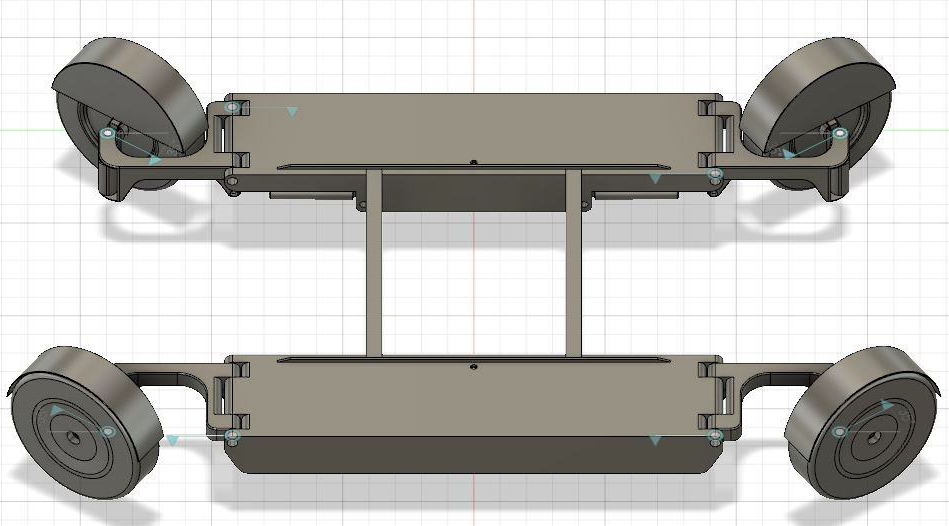

numMo = 4;

Vollastkennlinie des gesamten Antriebs (alle vier Motoren zusammen)

figure
plot(n_Mo_plot_rpm,numMo*M_Mo_plot,'k')
X = numMo*M_Mo_plot

X =   373.2000  373.2000         0


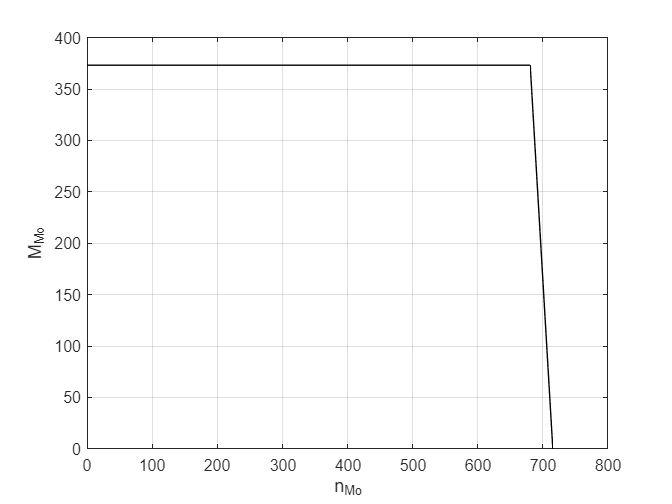

grid on
ylim([0 400])
xlabel('n_{Mo}')
ylabel('M_{Mo}')
hold on

Verlauf des Normalfahrwiderstands $F_{W0}$

v_FW_plot = [0:10:100]/3.6;
n_FW_plot = v_FW_plot/rA*30/pi;
F_W0_plot = m*g*fR + cw*A*rho/2*v_FW_plot.^2;
M_W0_plot = F_W0_plot*rA;

%plot(n_FW_plot,M_W0_plot,'b')

Beschleunigung ist zu Beginn des Anfahrvorgangs in der Ebene

aAnf = (4*M_Mo_cont/rA - m*g*fR)/m

aAnf = 1.2348

Mögliche Steigung am Ende der Leistungshyperbel

alpha = asind(((4*M_Mo_cont)/rA - m*g*fR - cw*A*rho/2*(v_Mo_cont_kph/3.6)^2)/(m*g));
q=tand(alpha)*100

q = 9.6831

## **Betriebspunkte (KFZSYS SS2022)**

Die Fahrzeuggeschwindigkeit beträgt $v$=40km/h. Das Fahrzeug beschleunigt mit $a$=0,56m/s². Bestimmen Sie den Betriebspunkt.

v_40_mps = 40/3.6;
n_40_rpm = v_40_mps/rA *30/pi

n_40_rpm = 303.1523

a_40_mps2 = 0.56;
M_40 = (m*a_40_mps2 + m*g*fR + cw*A*rho/2*v_40_mps^2)*rA

M_40 = 200.3421

figure
subplot(1,2,1)
plot(n_Mo_plot_rpm,numMo*M_Mo_plot,'k')
hold on
plot(n_FW_plot,M_W0_plot,'k:')
grid on
ylim([0 400])
xlabel('n_{Mo}')
ylabel('M_{Mo}')
plot(n_40_rpm,M_40,'bo')

subplot(1,2,2)
plot(n_Mo_plot_rpm,M_Mo_plot,'k')
hold on
grid on
ylim([0 100])
xlabel('n_{Mo}')
ylabel('M_{Mo}')
plot(n_40_rpm,0.25*M_40,'bo')

Mit welcher Spannung werden die Motoren betrieben, um den Betriebspunkt zu ermöglichen?

I_40=0.25*M_40/c_Mo

I_40 = 78.1497

U_40= R_A*I_40 + c_Mo*n_40_rpm*pi/30

U_40 = 21.5962

Leerlaufdrehzahl bei dieser Spannung

n_40_0 = (U_40*30)/(c_Mo*pi)

n_40_0 = 321.7832

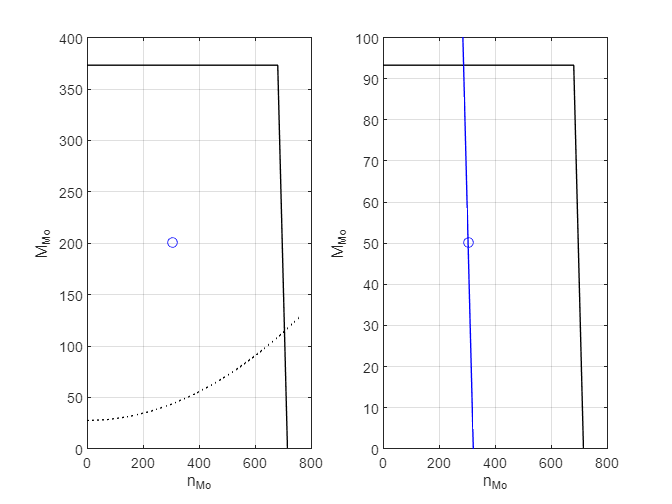

n_Kl_plot = [250:10:(n_40_0+10)];
M_kl_plot = U_40/R_A*c_Mo - pi/30*c_Mo^2/R_A*n_Kl_plot;
plot(n_Kl_plot,M_kl_plot,'b')

Welchen Wirkungsgrad hat der Motor in diesem Betriebspunkt. 

P_40_el=I_40*U_40  

P_40_el = 1.6877e+03

P_40_mech = 0.25*M_40*n_40_rpm*pi/30

P_40_mech = 1.5900e+03

eta_40= P_40_mech/P_40_el

eta_40 = 0.9421

## **Batterie**

Die Batterie soll aus LiFePo4 Rundzellen vom Typ 26650 aufgebaut werden. Hersteller A123

[https://www.i-tecc.de/shop/media/pdf/a7/b3/7f/A123-Systems-26650-Data-Sheet-2015.pdf](https://www.i-tecc.de/shop/media/pdf/a7/b3/7f/A123-Systems-26650-Data-Sheet-2015.pdf)

[https://lygte-info.dk/review/batteries2012/A123%20ANR26650M1B%202500mAh%20%28Green%29%20UK.html](https://lygte-info.dk/review/batteries2012/A123%20ANR26650M1B%202500mAh%20%28Green%29%20UK.html)

E_Bat =      6000;
U_B0 =       52;
C_Cell_Ah =  2.5;
U_Cell_V =   3.3;
R_i =        0.007;


Dimensionierung (nicht Teil der Prüfung)

numSer = U_B0/U_Cell_V

numSer = 15.7576

C_Bat_Ah = E_Bat/U_B0

C_Bat_Ah = 115.3846

numPar = C_Bat_Ah/C_Cell_Ah

numPar = 46.1538

numCell= numSer*numPar

numCell = 727.2727

Welche Leerlaufspannung benötigt die Batterie, wenn die Motoren am Eckpunkt mit 48V betrieben werden sollen?

U_B0_1 = U_Mo_nom + 4*R_i*M_Mo_cont/c_Mo

U_B0_1 = 52.0762

Die Batterie wird entladen und die Leerlaufspannung sinkt auf $U_{B0}^\star$=0,9 $U_{B0}$. Der Widerstand der Motoren nimmt aufgrund der Temperatur auf $R_A^\star$ = 1,1$R_A$ zu. Weiterhin benötigen zusätzliche Verbraucher einen Strom von $I_V$=100A. Bis zu welcher Drehzahl kann das Dauermoment noch aufgebracht werden.

MGL: $U_{B0}^\star - R_i\left( 4I_A + I_v\right) = I_A\cdot R_A + U_i$ und daraus


$$n_{Mo}^\star = \frac{U_{B0}^\star - R_i \cdot I_v}{\frac{\pi}{30}c_{Mo}} - \frac{4R_i +R_A^\star}{\frac{\pi}{30}c_{Mo}^2}M_{Mo}^D$$


U_B0_2 = 0.9*U_B0_1;
R_A_2 = 1.2*R_A;
I_v=100;
n_star_rpm = (U_B0_2-R_i*I_v)/(pi/30*c_Mo)-(R_A_2+4*R_i)/(pi/30*c_Mo^2)*M_Mo_cont

n_star_rpm = 585.5294

v_star_kph = n_star_rpm*pi/30*rA*3.6

v_star_kph = 77.2588

## Kommunikation

### Intel Botschaft

ID = dec2bin(212)

ID = '11010100'

Speed_phys = 300;
Speed_Offset = -1600;
Speed_Fak = 0.05;
Speed_dec = (Speed_phys - Speed_Offset)/Speed_Fak

Speed_dec = 38000

Speed_bin = dec2bin(Speed_dec)

Speed_bin = '1001010001110000'

Torque_phys = 50;
Torque_Offset = -150;
Torque_Fak = 0.005;
Torque_dec = (Torque_phys - Torque_Offset)/Torque_Fak

Torque_dec = 40000

Torque_bin = dec2bin(Torque_dec)

Torque_bin = '1001110001000000'

Current_phys = 78;
Current_Offset = -200;
Current_Fak = 0.4;
Current_dec = (Current_phys - Current_Offset)/Current_Fak

Current_dec = 695

Current_bin = dec2bin(Current_dec)

Current_bin = '1010110111'